## Question 2

clear;
clc;

load('402123100-q2.mat')

### >>> 2.0 - Initial Assignments

na = 3*n;
nb = 3*n;
p = na+nb;
N = length(id.u);

### >>> 2.1 - RLS Function

>>> Write the following piece of code in a separate `.m` file and save it in the same directory as the current file.

% function [theta, U] = RLS(na, nb, th0, p0, u, y)
%     
%     p = na + nb;
%     N = length(y);
%     theta = th0;
%     P = p0 * eye(na + nb);
% 
%     theta_estimate=th0';
% 
%     U=[];
%     Y=[];
% 
%     for i=1:N
%         Y = [Y ; y(i)];
%    
%         Ut=zeros(1,p);
%         Y1=y(i);
%         for j=1:na
%             if (i-j>0)
%                 Ut(1,j) = -y(i-j);
%             end
%         end
%         for j=na+1:na+nb
%             k=j-na;
%             if (i-k>0)
%                 Ut(1,j) = u(i-k);
%             end
%         end
%     
%         U=[U;Ut];
%         Kt=(P*Ut')/(1+Ut*P*Ut');
%         theta = theta + Kt*(Y1 - Ut*theta);
%         theta_estimate = [theta_estimate ; theta'];
%         P = (eye(na+nb) - Kt*Ut) * P;
%     end
%     
% end


### **>>> 2.2 - ARX Modeling**

#### **        2.2.0 Data Split**

data10 = id(1:floor(length(id.u)*0.1));
data100 = id;

#### **        2.2.1 ARX Modeling - 100% of Data**

U100 = arx_U_builder(na, nb, data100.u, data100.y);
theta_hat100 = inv(U100'*U100)*U100'*data100.y;

[theta100, U100] = RLS(na, nb, theta_hat100, 0.01*eye(p), data100.u, data100.y);
y100 = U100*theta100;

>>> theta with 100% of data:

theta100'

ans =     0.0265   -0.3508   -0.3159   -0.2247   -0.2263   -0.0957   -0.0737    0.1100    0.2656    4.0665    3.7376    1.5922   -0.0868   -1.0774   -1.9352   -2.0885   -2.1214   -1.3308


#### **2.2.2 ARX Modeling - 10% of Data**

U10 = arx_U_builder(na, nb, data10.u, data10.y);
theta_hat10 = inv(U10'*U10)*U10'*data10.y;

[theta10, U10] = RLS(na, nb, theta_hat10, 0.01*eye(p), data10.u, data10.y);
y10 = U10*theta10;

>>> theta with 10% of data:

theta10'

ans =     0.0337   -0.3867   -0.1876   -0.4060   -0.2768    0.0985   -0.0081    0.2102    0.0902    2.5565    4.0955    1.9083    0.2724   -1.2637   -2.3546   -1.9254   -1.6677   -0.1276


#### **>>> 2.2.3 - Plot both 100% and 10%**

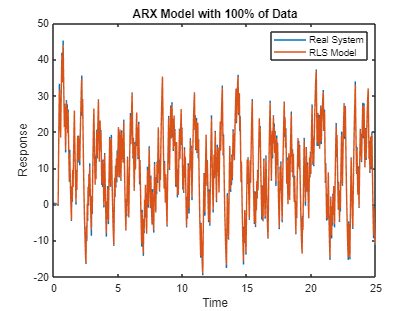

t100 = (data100.Tstart:data100.Ts:N*data100.Tstart);
t10 = (data10.Tstart:data10.Ts:floor(N*0.1)*data10.Tstart);

figure(1)
plot(t100,data100.y,t100,y100)
title("ARX Model with 100% of Data")
xlabel("Time")
ylabel("Response")
legend('Real System','RLS Model')

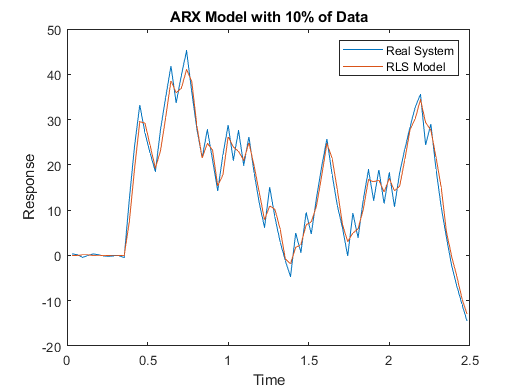


figure(2)
plot(t10,data10.y,t10,y10)
title("ARX Model with 10% of Data")
xlabel("Time")
ylabel("Response")
legend('Real System','RLS Model')

>>> R2 values for both approaches:

       100% of data:

r2_rls_100 = rSQR(data100.y, y100)

r2_rls_100 = 0.9979

       10% of data:

r2_rls_10 = rSQR(data10.y, y10)

r2_rls_10 = 0.9619